converting images to grayscale images

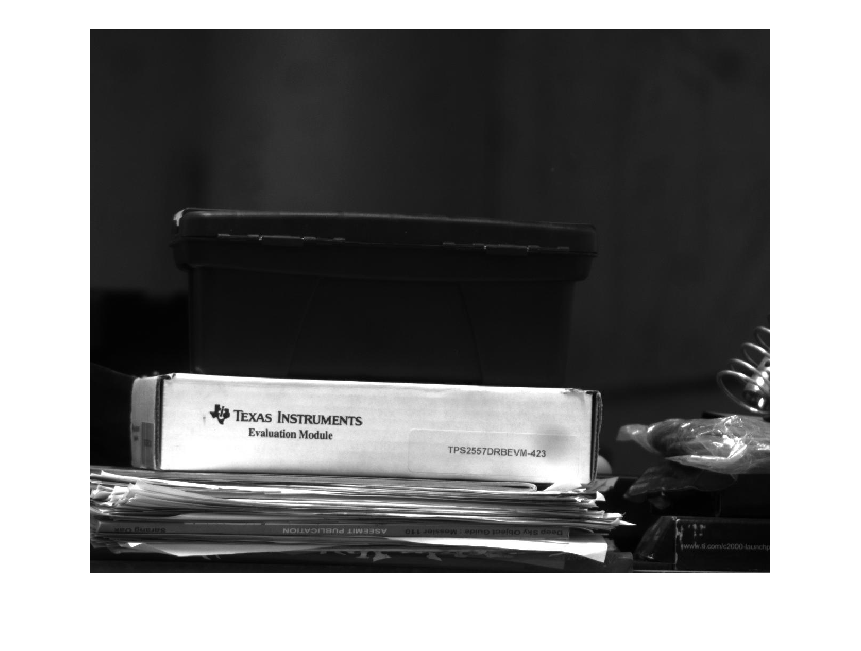

rgbimage1 = imread('testimage1.jpeg');
imshow(rgbimage1)

grayscale1 = im2gray(rgbimage1);
imshow(grayscale1)


rgbimage2 = imread('testimage1.jpeg');
imshow(0.8*rgbimage2)

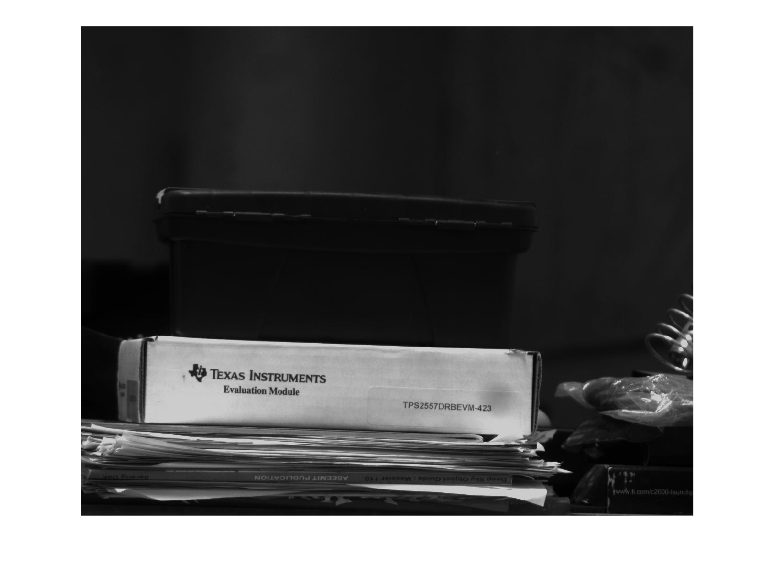

grayscale2 = im2gray(0.8*rgbimage2);
imshow(grayscale2)

getting histogram of intensities of images ranging from 0 to 255

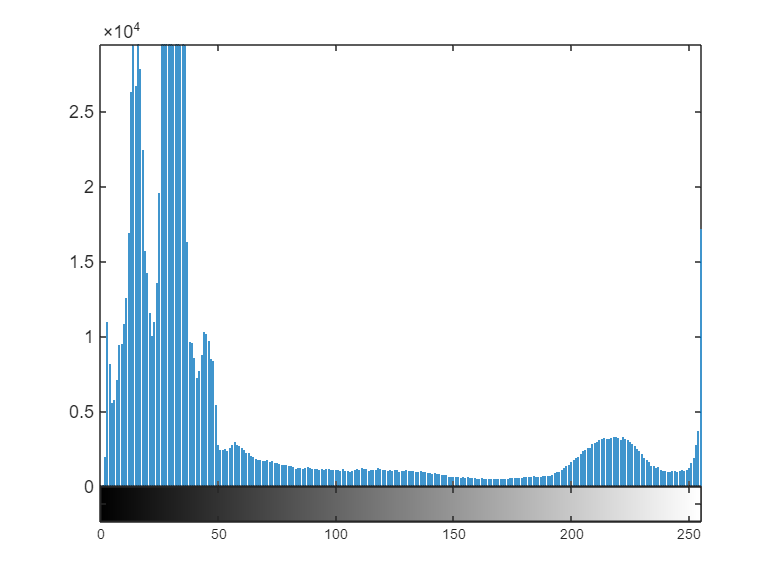

imhist(grayscale1)

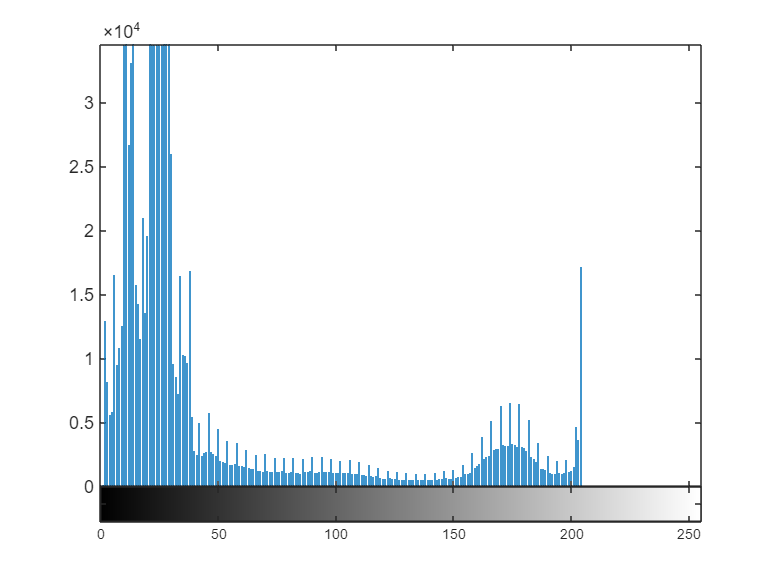

imhist(grayscale2)

getting mean intensity value of the images, which is the average DN value

DN1 = mean(grayscale1(:))

DN1 = 58.0230

DN2 = mean(grayscale2(:))

DN2 = 46.4253

put in the radiance values in W/m^2-sr

radiance1 = 100

radiance1 = 100

radiance2 = 0.8*radiance1 

radiance2 = 80

creating straight line plot between (radiance1, DN1) and (radiance2, DN2)

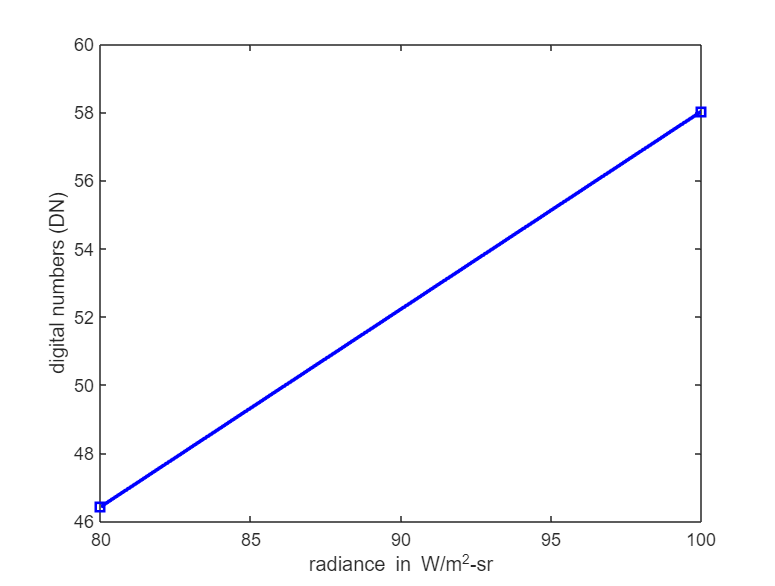

plot([radiance1,radiance2,] , [DN1, DN2] , '-sb', 'LineWidth',2);
xlabel('radiance in W/m^2-sr')
ylabel('digital numbers (DN)')

gain = (DN2-DN1)/(radiance2-radiance1)

gain = 0.5799

bias = DN1 - gain*radiance1

bias = 0.0348